[normalData,normalSampleRate] = audioread("pat_42_3.wav");
normalVoice = timetable(normalData, 'SampleRate', normalSampleRate, 'VariableNames', "Data")

normalVoice = 433944×1 timetable
         Time            Data    
    ______________    ___________

    0 sec             -0.00042725
    2.2676e-05 sec     0.00021362
    4.5351e-05 sec     3.0518e-05
    6.8027e-05 sec    -0.00054932
    9.0703e-05 sec    -6.1035e-05
    0.00011338 sec              0
    0.00013605 sec     0.00082397
    0.00015873 sec      0.0012512
    0.00018141 sec      0.0013733
    0.00020408 sec      0.0019226
    0.00022676 sec      0.0021057
    0.00024943 sec      0.0023499
    0.00027211 sec      0.0027161
    0.00029478 sec      0.0030518
    0.00031746 sec      0.0030212
    0.00034014 sec      0.0019226


normalSampleRate

normalSampleRate = 44100

%Uncomment and execute section to play the voice track
sound(normalVoice.Data, normalSampleRate)

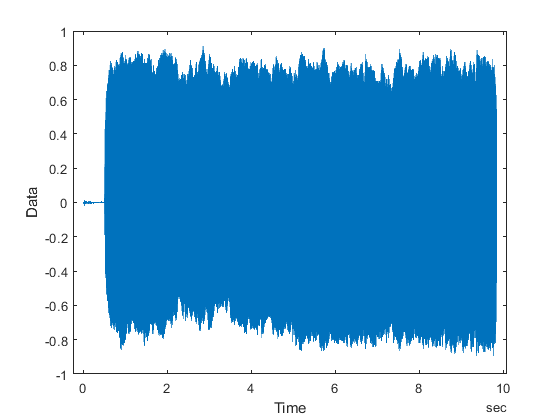

%Plotting the waveform
plot(normalVoice.Time, normalVoice.Data)
xlabel("Time")
ylabel("Data")

%Cutting of initial silent part of the signal
normalVoice2= normalVoice(normalVoice.Time > seconds(0.51), :)

normalVoice2 = 411452×1 timetable
       Time         Data  
    ___________    _______

    0.51002 sec     0.1889
    0.51005 sec    0.18982
    0.51007 sec    0.18359
    0.51009 sec    0.17642
    0.51011 sec    0.17114
    0.51014 sec    0.17209
    0.51016 sec    0.17902
    0.51018 sec    0.18854
    0.5102 sec     0.19827
    0.51023 sec     0.2034
    0.51025 sec    0.20667
    0.51027 sec    0.20639
    0.51029 sec    0.19461
    0.51032 sec    0.16946
    0.51034 sec    0.13593
    0.51036 sec     0.1033


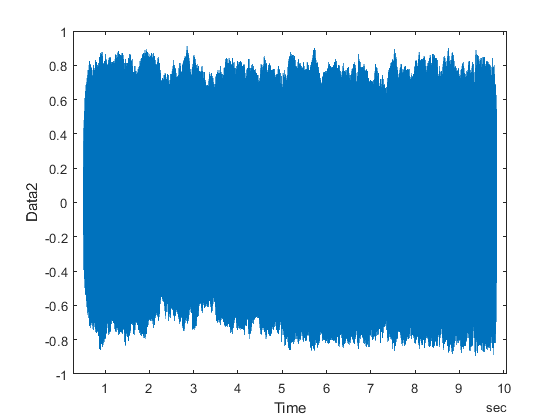

%Plotting the waveform
plot(normalVoice2.Time, normalVoice2.Data)
xlabel("Time")
ylabel("Data2")

normalVoice2.Time= normalVoice2.Time - normalVoice2.Time(1)

normalVoice2 = 411452×1 timetable
         Time          Data  
    ______________    _______

    0 sec              0.1889
    2.2676e-05 sec    0.18982
    4.5351e-05 sec    0.18359
    6.8027e-05 sec    0.17642
    9.0703e-05 sec    0.17114
    0.00011338 sec    0.17209
    0.00013605 sec    0.17902
    0.00015873 sec    0.18854
    0.00018141 sec    0.19827
    0.00020408 sec     0.2034
    0.00022676 sec    0.20667
    0.00024943 sec    0.20639
    0.00027211 sec    0.19461
    0.00029478 sec    0.16946
    0.00031746 sec    0.13593
    0.00034014 sec     0.1033


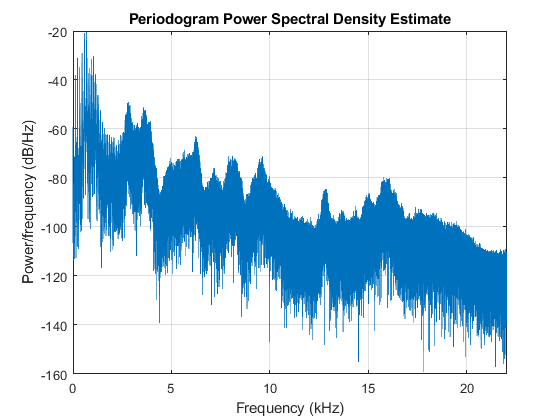

[normalSpectrum, normalFrequencies] = periodogram(normalVoice2.Data, [], [], normalSampleRate);
periodogram(normalVoice2.Data, [], [], normalSampleRate);

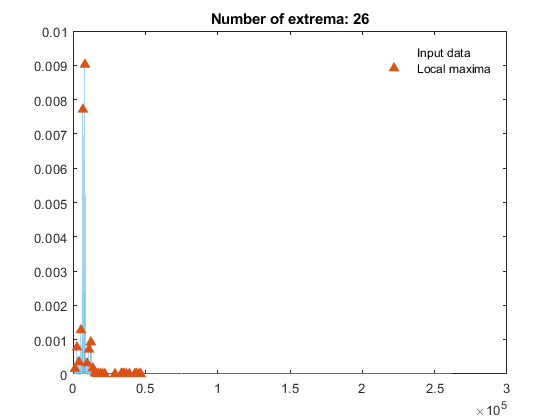

% Find local maxima
normalPrimaryPeaks = islocalmax(normalSpectrum,'MinProminence',5e-07,...
    'MinSeparation',1000);

% Display results
clf
plot(normalSpectrum,'Color',[109 185 226]/255,'DisplayName','Input data')
hold on

% Plot local maxima
plot(find(normalPrimaryPeaks),normalSpectrum(normalPrimaryPeaks),'^','Color',[217 83 25]/255,...
    'MarkerFaceColor',[217 83 25]/255,'DisplayName','Local maxima')
title(['Number of extrema: ' num2str(nnz(normalPrimaryPeaks))])
hold off
legend

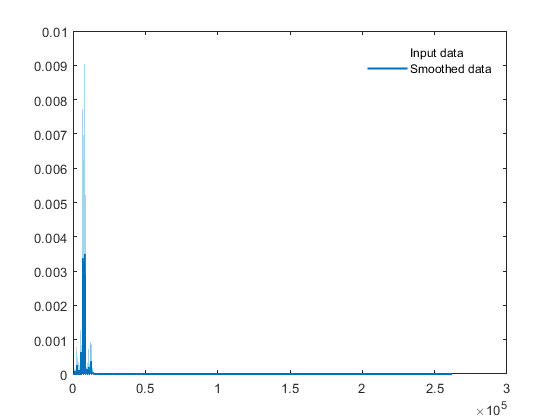

% Smooth input data
smoothedData = smoothdata(normalSpectrum,'movmedian',10);

% Display results
clf
plot(normalSpectrum,'Color',[109 185 226]/255,'DisplayName','Input data')
hold on
plot(smoothedData,'Color',[0 114 189]/255,'LineWidth',1.5,...
    'DisplayName','Smoothed data')
hold off
legend